**1a**.) Given $x' = x - m$


$$J = \sum_{i = 1}^{n}(m' + a_ie - x'_i)^2
\\ where \ m' \ is \  the \ mean \ of \  x'.
\\
\\ Let \ u = m' + a_ie - x'_i
\\ \therefore  J = \sum_{i = 1}^{n}(u^T u)
\\
\\  \frac{\partial J} {\partial a_i} = 0 = \frac {\partial u^Tu}{\partial a_i}

\\ But \ \frac{\partial u}{\partial a_i} = e
\\ and \  \frac{\partial u^T u}{\partial u} = 2u^T

\\\therefore \frac{\partial J}{\partial a_i} = 0
= \frac{\partial u^Tu}{\partial u}
\frac{\partial u}{\partial a_i}
\\ \qquad = 2u^Te
\\ \qquad = u^Te = (m' + a_ie - x'_i)^Te
\\ \qquad = {m'}^Te + a_i - {x'}^T_ie

\\ where \ we \ have \ used \ the \ constraint \ e^Te = 1

\\\therefore a_i = ({x'_i} - m')^Te
\\
\\ This \ is \ similar \ to \ the \ result
\\ a_i = (x_i - m)^Te 
\\ gotten \ for \ the \ variable \ x \ except \ with
\\ \ mean \ now \ different.
\\ We \ know \ that \ the \ mean \ of \ a \ mean-shifted \ vairable \ is \ 0

\\ \therefore m'  = 0.
\\ and \ a_i = {x'_i}^Te 

\\ since \ x' = x - m

\\ \therefore a_i = (x_i -  m)^Te
\\ which \ is \ the \ same \ PCA \ representation \ for \ x.

\\ \therefore The \ PCA \ representation \ is \ unchanged.$$



$$By \ using \ the \ scatter \ matrix \ S \ it \ can 
\\ \ also \ be \ shown \ that \ the \ eigenvectors 
\\ \ are \ also \ unchanged.
\\ From
\\ Se  = \lambda e
\\ Where \ the \ scatter \ matrix \ S \ is
\\ S = \sum_{i = 1}^{n}(x_i - m)(x_i - m)^T
\\
\\ Similarly \ for \ the \ centered \ x'
\\ S' =  \sum_{i = 1}^{n}(x'_i - m')(x'_i - m')^T
\\ As \ already \ stated \ 
\\ m' = 0
\\ \therefore S' = \sum_{i = 1}^{n}(x'_i)(x'_i)^T
\\ and \ x' = x - m
\\ \therefore S' = \sum_{i = 1}^{n}(x_i - m)(x_i - m)^T = S
\\ \therefore \ the \ direction (eigenvector) \ is \ also \ unchanged$$


**1b.) **$Given \ y = \gamma x
\\ Proceeding \ as \ before
\\ a_{iy} = (y_i - m_y)^Te_y
\\ where \ m_y \ is \ the  \ mean \ of \ y
\\ m_y = \frac{1}{n} \sum_{i=1}^{n}(\gamma x) = \gamma m
\\ where \ m \ is \ the \ mean \ of \ x
\\
\\ \therefore a_{iy} = (\gamma x_i - \gamma m)^Te
\\ \qquad = \gamma(x_i - m)^Te
\\
\\ which \ shows \ that \ the \ PCA \ representation \ of \ 
\\ y = \gamma x \ is \ a \ scaled \ version \ of \ the \ original \ x \ provided \ that \ they \ have
\\ the \ same \ eigenvectors \ e.
\\
\\ Recall \ that \ the \ eigenvectors \ are \ \\ related \ to \ the \ scatter \ matrix \ by
\\ S_ye_y = \lambda e_y
\\and \ for \ x
\\ S_xe_x = \alpha e_x
\\ S_y  = \sum_{i = 1}^{n}(y_i- m_y)(y_i - m_y)^T
\\ \quad = \sum_{i = 1}^{n}(\gamma x_i - \gamma m)(\gamma x_i - \gamma m)^T
\\ \quad = \gamma^2 S_x
\\ \therefore \gamma^2 S_x e_y = \lambda e_y
\\ S_x e_y = \frac {\lambda}{\gamma^2} e_y
\\ which \ shows \ that \ the \ e_y \ are \ also \ \\ eigenvectors \ of \ S_x
\\ \therefore \ for \ y = \gamma x \ the \ PCA
\\ representation \ is \ a \ scaled \ version \ of \ 
\\ the \ representation \ of \ x \ but \ the \ 
\\  directions \ remain \ the \ same.$

## Load Data

chair = readtable('DataSet2020\dataset_example\chair\train.txt');
desk = readtable("DataSet2020\dataset_example\desk\train.txt");
sofa = readtable("DataSet2020\dataset_example\sofa\train.txt");
tabled = readtable("DataSet2020\dataset_example\table\train.txt");
toilet = readtable("DataSet2020\dataset_example\toilet\train.txt");

chair_test = readtable('DataSet2020\dataset_example\chair\test.txt');
desk_test = readtable("DataSet2020\dataset_example\desk\test.txt");
sofa_test = readtable("DataSet2020\dataset_example\sofa\test.txt");
tabled_test = readtable("DataSet2020\dataset_example\table\test.txt");
toilet_test = readtable("DataSet2020\dataset_example\toilet\test.txt");

train_data = [chair; desk; sofa; tabled; toilet];

test_data = [chair_test; desk_test; sofa_test; tabled_test; toilet_test];

## Question 2. Train.

class_err = zeros(5, 399);

for i = 1:5
    data = train_data((100*(i-1))+1:100*i, :);
    data_mean = mean(data{:, :});
    [V, D] = get_eig(data, 400);
    data = data{:, :} - data_mean;
    new_pattern = data*V;
    for j = 1:399
        first_j_col = new_pattern(:, 400-j+1:400);
        reconst = data_mean + (first_j_col * V(:, 400-j+1:400)');
        rec_err = (data + data_mean) - reconst;
        rec_err = rec_err.^2;
        rec_err = sum(rec_err, 2);
        rec_err = sqrt(rec_err);
        class_err(i, j) = mean(rec_err);
    end
end

   1.7117e+23



  -8.2084e+24



  -2.6321e+25



   2.1204e+24



  -3.9488e+23



E_d = mean(class_err);

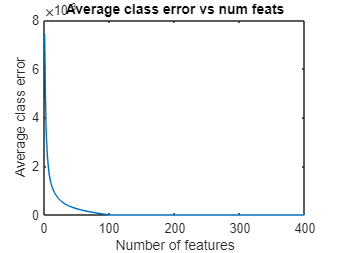

plot(1:399, E_d);
xlabel("Number of features");
ylabel("Average class error");
title("Average class error vs num feats")

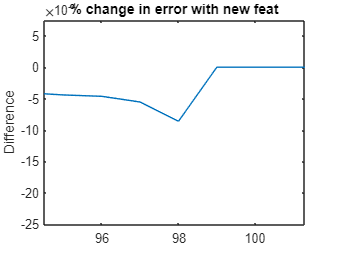

plot(diff(E_d)*100)

xlim([94.49 101.30])
ylim([-0.00251 0.00075])
title("% change in error with new feat")
ylabel("Difference")

From the last plot, after the 99th feature each new additional feature does not offer much difference, therefore d* is chosen as 99.

## Test

class_err_test = zeros(5, 1);

for i = 1:5
    data = train_data((100*(i-1))+1:100*i, :);
    test = test_data((25*(i-1))+1:25*i, :);

    data_mean = mean(data{:, :});

    %scatter_mat = (data' * data);
    [V, D] = get_eig(data, 400);
    
    data = data{:, :} - data_mean;
    test = test{:, :} - data_mean;

    %new_pattern = data*V;
    new_pattern_test = test*V;

    first_j_col = new_pattern_test(:, 400-99+1:400);

    reconst_test = data_mean + (first_j_col * V(:, 400-99+1:400)');
    
    rec_err_test = (test + data_mean) - reconst_test;
    rec_err_test = rec_err_test.^2;
    rec_err_test = sum(rec_err_test, 2);
    rec_err_test = sqrt(rec_err_test);

    class_err_test(i) = mean(rec_err_test);
end

% Mean error for test set
test_error = mean(class_err_test)

test_error = 5.6596e-04

The test error and the train at **d = 99** are very small with the test error being $\textrm{test}\_\textrm{error}=\textrm{mean}\left(\textrm{class}\_\textrm{err}\_\textrm{test}\right)=5\ldotp 6596e-04\;$ and the train error at $d^* =E_d \left(99\right)=9\ldotp 7725e-13\;$

## Question 3

%eigenvectors for each class at d = 99
d_chosen = 99;
[V_chair, D_chair] = get_eig(chair, d_chosen);
[V_desk, D_desk] = get_eig(desk, d_chosen);
[V_sofa, D_sofa] = get_eig(sofa, d_chosen);
[V_tabled, D_tabled] = get_eig(tabled, d_chosen);
[V_toilet, D_toilet] = get_eig(toilet, d_chosen);

%new_patterns
new_chair = (chair{:, :} - mean(chair{:, :})) * V_chair;
m_new_chair = mean(new_chair);

new_desk = (desk{:, :} - mean(desk{:, :})) * V_desk;
m_new_desk = mean(new_desk);

new_sofa = (sofa{:, :} - mean(sofa{:, :})) * V_sofa;
m_new_sofa = mean(new_sofa);

new_tabled = (tabled{:, :} - mean(tabled{:, :})) * V_tabled;
m_new_tabled = mean(new_tabled);

new_toilet = (toilet{:, :} - mean(toilet{:, :})) * V_toilet;
m_new_toilet = mean(new_toilet);

%scatter S_W
scatter_chair = (new_chair - m_new_chair)' * (new_chair - m_new_chair);
scatter_desk = (new_desk - m_new_desk)' * (new_desk - m_new_desk);
scatter_sofa = (new_sofa - m_new_sofa)' * (new_sofa - m_new_sofa);
scatter_tabled = (new_tabled - m_new_tabled)' * (new_tabled - m_new_tabled);
scatter_toilet = (new_toilet - m_new_toilet)' * (new_toilet - m_new_toilet);

S_W = scatter_toilet + scatter_tabled + scatter_sofa + scatter_desk + ...
scatter_chair;

%scatter S_B
m = mean([new_chair; new_desk; new_sofa; new_tabled; new_toilet]);
class_means = [m_new_chair; m_new_desk; m_new_sofa; new_tabled; new_toilet];

S_B = ((class_means - m)' * (class_means - m))*100; % ni = 100 for each class

The best Ws are:

%Best W
[W, W_D] = eig(inv(S_W)*S_B);

Maximum number of features that can be determined is $c-1=5-1=4$. So the 4 largest eigenvectors are chosen below.

[s, ind] = sort(diag(W_D));
W = W(:, ind);
W = W(:, end-4+1:end)

W =    -0.0000   -0.0000   -0.0000   -1.0000
   -0.0000    0.0000   -1.0000    0.0000
    0.0000   -1.0000   -0.0000    0.0000
    1.0000    0.0000   -0.0000   -0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000   -0.0000   -0.0000
   -0.0000    0.0000    0.0000   -0.0000
    0.0000   -0.0000   -0.0000   -0.0000
   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0000    0.0000   -0.0000   -0.0000


J is:

num = det(W' * S_B * W);
denom = det(W' * S_W * W);
J = num/denom

J = 3.6425e+07

%FLD representation
chair_fld = new_chair * W;
desk_fld = new_desk * W;
sofa_fld = new_sofa * W;
tabled_fld = new_tabled * W;
toilet_fld = new_toilet * W;

%pca similarity
pca_rep = [new_chair; new_desk; new_sofa; new_tabled; new_toilet];
sim_pca = similarity_matrix(pca_rep, 100);

%fld similarity
fld_rep = [chair_fld; desk_fld; sofa_fld; tabled_fld; toilet_fld];
sim_fld = similarity_matrix(fld_rep, 100);

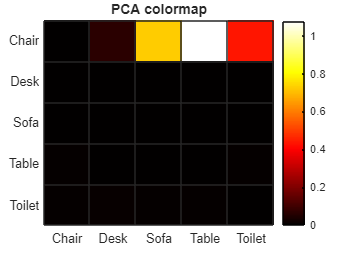

%multiplying by 10 as this makes matlab display the values in the map
h_pca = heatmap(sim_pca*10, "Colormap", hot, 'Title', 'PCA colormap');
h_pca.XDisplayLabels = {'Chair', 'Desk', 'Sofa', 'Table', 'Toilet'};
h_pca.YDisplayLabels = {'Chair', 'Desk', 'Sofa', 'Table', 'Toilet'};

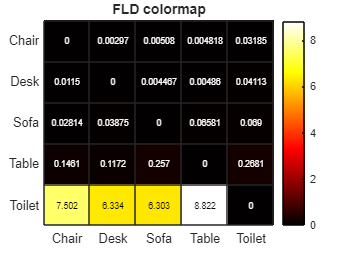

h_fld = heatmap(sim_fld*10^9, 'Colormap', hot, 'Title', 'FLD colormap');
h_fld.XDisplayLabels = {'Chair', 'Desk', 'Sofa', 'Table', 'Toilet'};
h_fld.YDisplayLabels = {'Chair', 'Desk', 'Sofa', 'Table', 'Toilet'};

## Test

%pca rep
test_chair_pca = (chair_test{:, :} - mean(chair{:, :})) * V_chair;

test_desk_pca = (desk_test{:, :} - mean(desk{:, :})) * V_desk;

test_sofa_pca = (sofa_test{:, :} - mean(sofa{:, :})) * V_sofa;

test_tabled_pca = (tabled_test{:, :} - mean(tabled{:, :})) * V_tabled;

test_toilet_pca = (toilet_test{:, :} - mean(toilet{:, :})) * V_toilet;

%fld rep
test_chair_fld = test_chair_pca * W;
test_desk_fld = test_desk_pca * W;
test_sofa_fld = test_sofa_pca * W;
test_tabled_fld = test_tabled_pca * W;
test_toilet_fld = test_toilet_pca * W;

%test pca similarity
test_pca_rep = [test_chair_pca; test_desk_pca; test_sofa_pca;
    test_tabled_pca; test_toilet_pca];
test_sim_pca = similarity_matrix(test_pca_rep, 25);

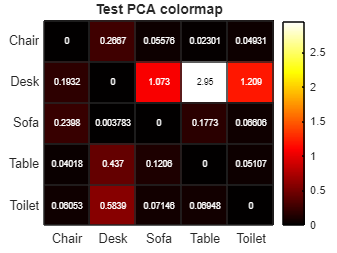

test_h_pca = heatmap(test_sim_pca*100, "Colormap", hot, 'Title',  ...
    'Test PCA colormap');
test_h_pca.XDisplayLabels = {'Chair', 'Desk', 'Sofa', 'Table', 'Toilet'};
test_h_pca.YDisplayLabels = {'Chair', 'Desk', 'Sofa', 'Table', 'Toilet'};

%test fld similarity
test_fld_rep = [test_chair_fld; test_desk_fld; test_sofa_fld; 
    test_tabled_fld; test_toilet_fld];
test_sim_fld = similarity_matrix(test_fld_rep, 25);

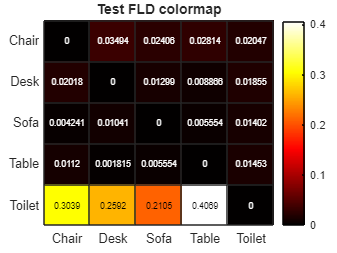

test_h_fld = heatmap(test_sim_fld*10^7, "Colormap", hot, 'Title', ...
    'Test FLD colormap');
test_h_fld.XDisplayLabels = {'Chair', 'Desk', 'Sofa', 'Table', 'Toilet'};
test_h_fld.YDisplayLabels = {'Chair', 'Desk', 'Sofa', 'Table', 'Toilet'};

### Pros and cons of FLD

FLD can be a great tool for data visualization as it can be used to reduce a very high dimensional vector into a 1d or 2d vector which can be easily plotted and understood.

By reducing the dimensionality of a vector, it can also help to make the job of the final classifier easier as the learned representation are usually very separated. The reduction in dimension can also speed up processing.

Although it can find good representations that separate the classes, this will not be true in cases where the classes are not linearly separable.

It can also require that the inverse of the scatter matrix be found, this can be a huge matrix for very high-dimensional data like image data and the calculation might be intractable.

function sim = similarity(c1, c2)
%Calculates the similarity s_ij between two classes
min_distances = zeros(size(c1, 1), 1);
for i = 1:size(c1, 1)
    sample = c1(1, :);
    min_distances(i) = min(sum((sample - c2).^2, 2));
end
sim = mean(min_distances);
end

function sim_matrix = similarity_matrix(rep, ni)
%creates the similarity matrix for all classes
sim_matrix = zeros(5, 5);
for i = 1:5
    c1 = rep((ni*(i-1))+1:ni*i, :);
    for j = 1:5
        c2 = rep((ni*(j-1))+1:ni*j, :);
        sim_matrix(i, j) = similarity(c1, c2);
    end
end
end

function [V_ret, D_ret] = get_eig(inp, dim)
%Finds and sorts dim biggest eigenvectors
inp_mean = mean(inp{:, :});

inp = inp{:, :} - inp_mean;

scatter = inp' * inp;
[V_ret, D_ret] = eig(scatter);
[~, idx] = sort(diag(D_ret));
D_ret = D_ret(idx, idx);
V_ret = V_ret(:, idx);

V_ret = V_ret(:, end-dim+1:end);
D_ret = D_ret(:, end-dim+1:end);
end